## Demo Adding Devices to Ribbons

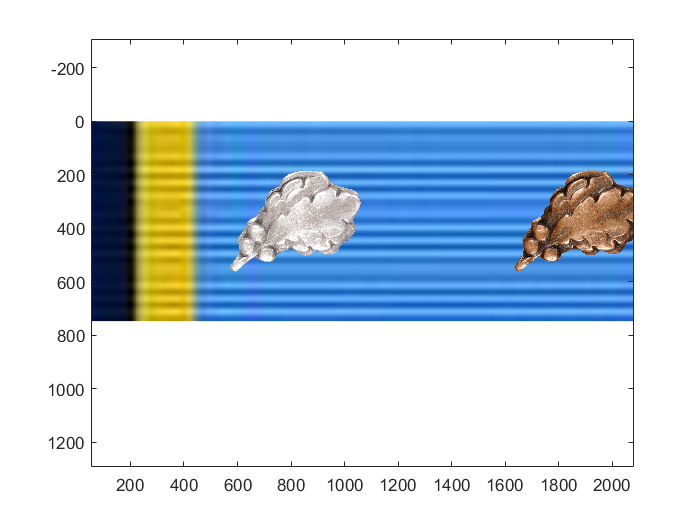

toppath = fullfile("HumanResources", "Redo", "SGC", "Decorations");
ribbon = imread(fullfile(toppath, "Ribbons", "AAM.jpg"));
device{1} = imread(fullfile(toppath, "Devices", "oak-silver.png"));
device{2} = imread(fullfile(toppath, "Devices", "oak-bronze.png"));
self = Ribbon(device, ribbon);
self.run;

## Demoing Scaling An Image to Another

scalePath = fullfile(toppath, "Devices", "oak-silver.png");
matchPath = fullfile(toppath, "Devices", "valor-bronze.png");
toScale = imread(scalePath);
toMatch = imread(matchPath);
scaler = size(toMatch, 1) / size(toScale, 1);
Img.scaleAndSave(scalePath, scaler);